clear
addpath(genpath('src'));

real_tests = {'sentinel','terrasarx'};
real_test = real_tests{1};
switch real_test
    case 'sentinel'
        nimg = double(imread('ref/real/Sentinel_band05.tif'));
        nimg = double(im2uint8(nimg / quantile(nimg(:),0.99)));
        rect = [3471 2272 4000 3000];
    case 'terrasarx'
        nimg = double(imread('ref/real/IMAGE_HH_SRA_spot_074_06.bmp'));
        rect = [31 51 80 160];
end        

figure;
imshow(uint8(nimg));

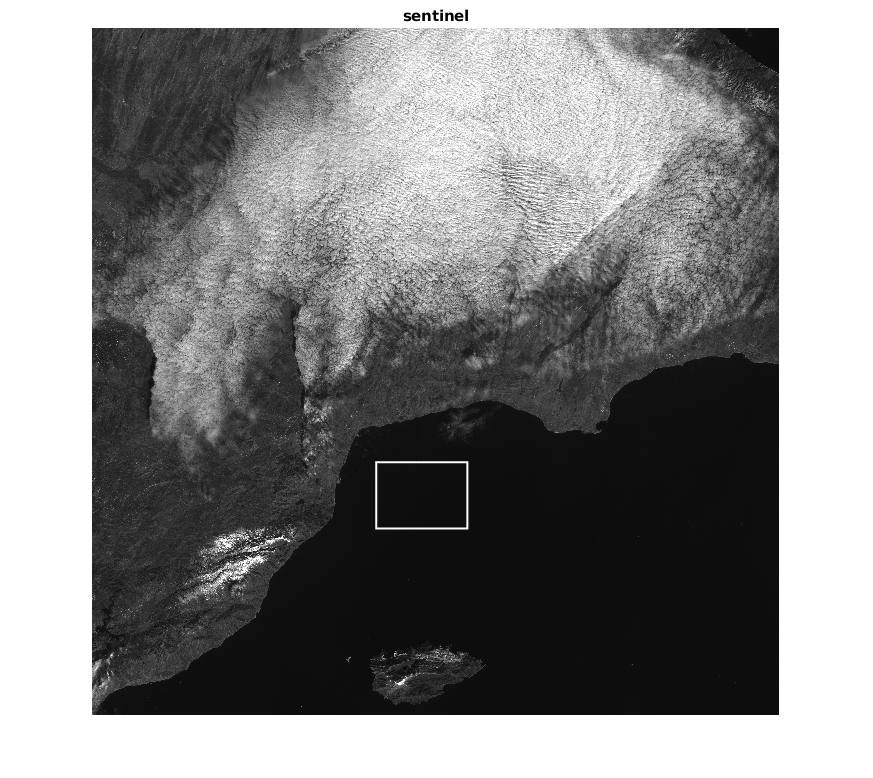

rectangle('Position',[rect(2) rect(1) rect(4)-rect(2) rect(3)-rect(1)],...
    'LineWidth',1.5,'EdgeColor',[1 1 1]);
title(real_test);

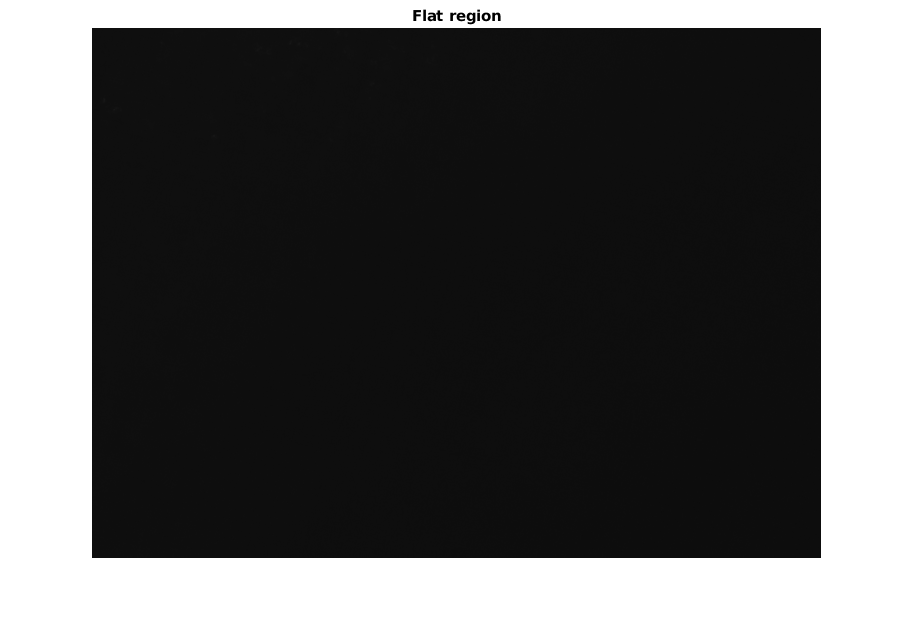

figure;
nimg = nimg(rect(1):rect(3),rect(2):rect(4));
imshow(uint8(nimg));
title('Flat region');

DCT normalized spectrum

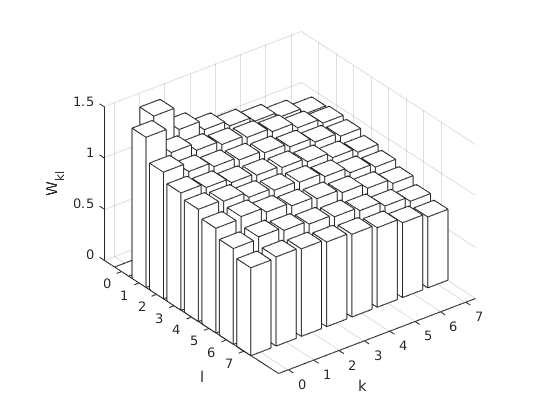

DCT_NPS = dct2Dnps_add_est(nimg,dctmtx(8));

figure;
bar3(DCT_NPS);
set(gca,'XTickLabel',{'0','1','2','3','4','5','6','7'},...
    'YTickLabel',{'0','1','2','3','4','5','6','7'});
xlabel('k');
ylabel('l');
zlabel('W_{kl}');
colormap white